A=[1 3;1 2]

A =      1     3
     1     2


nA=norm(A)

nA = 3.8643

nAt=norm(A')

nAt = 3.8643

norm(A*A')

ans = 14.9330

nA*nAt

ans = 14.9330

syms x y real; v=[x y]'

$$v = \left(\begin{array}{c} x\\ y \end{array}\right)$$


norm(A*A') % Euclidean Norm

ans = 14.9330

sqrt(eig(A*A'))

ans =     0.2588
    3.8643



Anorm=simplify(norm(A*v)/norm(v))

$$Anorm = \frac{\sqrt{2\,x^{2}+10\,x\,y+13\,y^{2}}}{\sqrt{x^{2}+y^{2}}}$$


eigA=eig(A'*A)

eigA =     0.0670
   14.9330


normA=sqrt(eigA)

normA =     0.2588
    3.8643


condN = max(normA)

condN = 3.8643

condn = min(normA)

condn = 0.2588

k=condN/condn

k = 14.9330

cond(A)

ans = 14.9330



[U,S,V]=svd(A)

U =    -0.8174   -0.5760
   -0.5760    0.8174


S =     3.8643         0
         0    0.2588


V =    -0.3606    0.9327
   -0.9327   -0.3606


sqrt(eig(A'*A))

ans =     0.2588
    3.8643


sv=diag(S);
cn=max(sv)/min(sv)

cn = 14.9330

clf;
syms q t real; rho=1.5;
x1=rho*cos(t); x2=rho*sin(t);
x=[x1;x2] % Curve

$$x = \left(\begin{array}{c} \frac{3\,\cos\left(t\right)}{2}\\ \frac{3\,\sin\left(t\right)}{2} \end{array}\right)$$

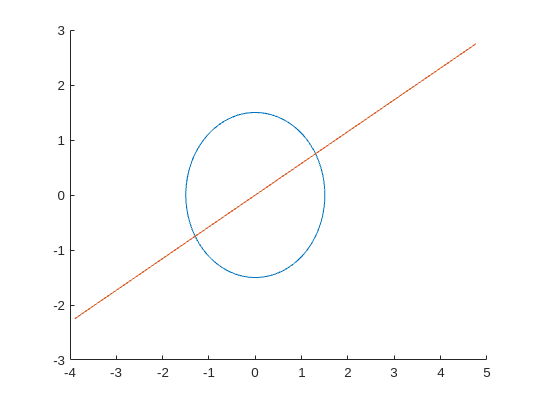

xp=diff(x);
t0=pi/6;
P0=subs(x,'t',t0);
xpP0=subs(xp,'t',t0);
N0=null(xpP0.');
N=P0+q*N0;
figure; hold on;
fplot(x1,x2);
fplot(N(1),N(2),[-3,2]);
hold off;


clf;
t=linspace(0,2*pi,101); rho=1.5; %Define curve with samples
x1=rho*cos(t); x2=rho*sin(t);
P=[x1;x2]; %sample points;
disp(P)

    1.5000    1.4970    1.4882    1.4734    1.4529    1.4266    1.3947    1.3572    1.3145    1.2665    1.2135    1.1558    1.0935    1.0268    0.9561    0.8817    0.8037    0.7226    0.6387    0.5522    0.4635    0.3730    0.2811    0.1880    0.0942    0.0000   -0.0942   -0.1880   -0.2811   -0.3730   -0.4635   -0.5522   -0.6387   -0.7226   -0.8037   -0.8817   -0.9561   -1.0268   -1.0935   -1.1558   -1.2135   -1.2665   -1.3145   -1.3572   -1.3947   -1.4266   -1.4529   -1.4734   -1.4882   -1.4970   -1.5000   -1.4970   -1.4882   -1.4734   -1.4529   -1.4266   -1.3947   -1.3572   -1.3145   -1.2665   -1.2135   -1.1558   -1.0935   -1.0268   -0.9561   -0.8817   -0.8037   -0.7226   -0.6387   -0.5522   -0.4635   -0.3730   -0.2811   -0.1880   -0.0942   -0.0000    0.0942    0.1880    0.2811    0.3730    0.4635    0.5522    0.6387    0.7226    0.8037    0.8817    0.9561    1.0268    1.0935    1.1558    1.2135    1.2665    1.3145    1.3572    1.3947    1.4266    1.4529    1.4734    1.4882    1.4970

j=10;
t0=t(j);
P0=P(:,j);
disp(P0)

    1.2665
    0.8037



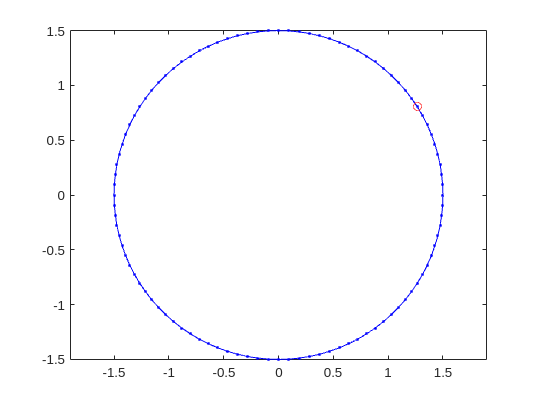

plot(P(1,:),P(2,:),'.b-',P0(1),P0(2),'or'); axis equal; hold on;



h=.0001;
t=linspace(0,2*pi,100);
X1p=(rho*cos(t+h) - rho*cos(t))/h; %Approximate derivative
X2p=(rho*sin(t+h) - rho*sin(t))/h;

X1p0=X1p(:,j)

X1p0 = -0.8110

X2p0=X2p(:,j)

X2p0 = 1.2618



q=linspace(-1,1,100);
T(1,:)=P0(1)+q.*X1p0;
T(2,:)=P0(2)+q.*X2p0;
disp(T(1,:))

    2.0775    2.0611    2.0447    2.0284    2.0120    1.9956    1.9792    1.9628    1.9464    1.9301    1.9137    1.8973    1.8809    1.8645    1.8481    1.8318    1.8154    1.7990    1.7826    1.7662    1.7498    1.7334    1.7171    1.7007    1.6843    1.6679    1.6515    1.6351    1.6188    1.6024    1.5860    1.5696    1.5532    1.5368    1.5204    1.5041    1.4877    1.4713    1.4549    1.4385    1.4221    1.4058    1.3894    1.3730    1.3566    1.3402    1.3238    1.3075    1.2911    1.2747    1.2583    1.2419    1.2255    1.2091    1.1928    1.1764    1.1600    1.1436    1.1272    1.1108    1.0945    1.0781    1.0617    1.0453    1.0289    1.0125    0.9962    0.9798    0.9634    0.9470    0.9306    0.9142    0.8978    0.8815    0.8651    0.8487    0.8323    0.8159    0.7995    0.7832    0.7668    0.7504    0.7340    0.7176    0.7012    0.6848    0.6685    0.6521    0.6357    0.6193    0.6029    0.5865    0.5702    0.5538    0.5374    0.5210    0.5046    0.4882    0.4719    0.4555

disp(T(2,:))

   -0.4581   -0.4326   -0.4071   -0.3816   -0.3561   -0.3306   -0.3051   -0.2797   -0.2542   -0.2287   -0.2032   -0.1777   -0.1522   -0.1267   -0.1012   -0.0757   -0.0502   -0.0247    0.0008    0.0262    0.0517    0.0772    0.1027    0.1282    0.1537    0.1792    0.2047    0.2302    0.2557    0.2812    0.3067    0.3321    0.3576    0.3831    0.4086    0.4341    0.4596    0.4851    0.5106    0.5361    0.5616    0.5871    0.6126    0.6380    0.6635    0.6890    0.7145    0.7400    0.7655    0.7910    0.8165    0.8420    0.8675    0.8930    0.9185    0.9439    0.9694    0.9949    1.0204    1.0459    1.0714    1.0969    1.1224    1.1479    1.1734    1.1989    1.2244    1.2498    1.2753    1.3008    1.3263    1.3518    1.3773    1.4028    1.4283    1.4538    1.4793    1.5048    1.5303    1.5557    1.5812    1.6067    1.6322    1.6577    1.6832    1.7087    1.7342    1.7597    1.7852    1.8107    1.8362    1.8616    1.8871    1.9126    1.9381    1.9636    1.9891    2.0146    2.0401    2.0656


T(1,j)

ans = 1.9301

T(2,j)

ans = -0.2287


nj1=nj(1)

nj1 = 0.8412

nj2=nj(2)

nj2 = 0.5407

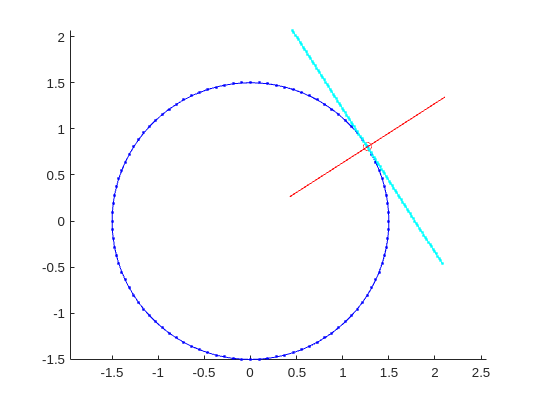


tangent_matrix=[X1p0; X2p0]';
nj=null(tangent_matrix);
N1=P0(1)+q.*nj1;
N2=P0(2)+q.*nj2;
N=[N1; N2];

figure; hold on;
plot(P(1,:),P(2,:),'.b-',P0(1),P0(2),'or'); axis equal; hold on;
plot(T(1,:),T(2,:),'.c-');
plot(N(1, :), N(2, :),'r-');
hold off;

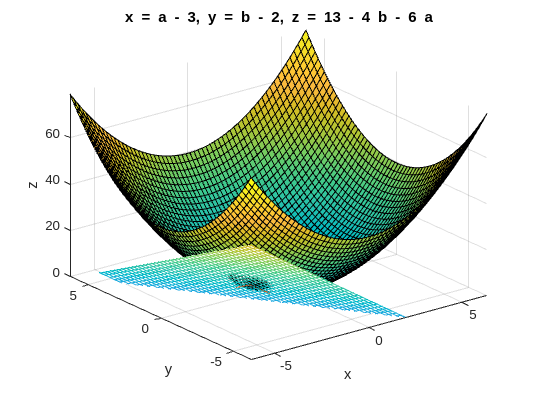


syms x y real; f=x^2+y^2;
X=-3; Y=-2; Z=subs(f,{'x','y'},{X,Y});
P=[x;y;f]; J=jacobian(P);
J0=subs(J,{x,y},{X,Y}); v=double(J0);
P0=[X Y Z]'; % Point P0
ezsurf(f); hold on; plot3(P0(1),P0(2),P0(3));
syms a b real; P=P0+J0*[a;b]; % tangent plane
ezmesh(P(1),P(2),P(3));
quiver3([X X], [Y Y], [Z Z], v(1,:), v(2,:),v(3,:),1)
hold off;

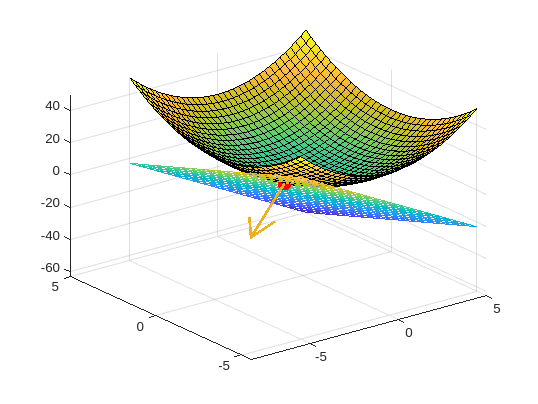


clf;
f=@(x,y) x.^2 + y.^2;
X=-3; Y=-2;

% Compute the function value at (X, Y)
Z = f(X, Y);

% Compute the Jacobian (gradient) numerically
dfdx = @(x, y) 2*x;
dfdy = @(x, y) 2*y;

J0 = [dfdx(X, Y); dfdy(X, Y)];
v = double(J0);

% Define the point P0
P0 = [X; Y; Z];

% Plot the surface f
figure;
fsurf(f, [-5 5 -5 5]); hold on;
plot3(P0(1), P0(2), P0(3), 'or', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Define the tangent plane
[X_grid, Y_grid] = meshgrid(-5:0.5:5, -5:0.5:5);
Z_tangent = Z + v(1)*(X_grid - X) + v(2)*(Y_grid - Y);
mesh(X_grid, Y_grid, Z_tangent, 'FaceAlpha', 0.5);

% Plot the gradient vector using quiver3
quiver3(X, Y, Z, v(1), v(2), 0, 'LineWidth', 2, 'MaxHeadSize', 2);

% Set plot properties
grid on;
hold off;